filename = 'data.txt';
formatSpec = '%f %f %d';
fileID = fopen('data.txt', 'r');
data = fscanf(fileID, formatSpec, [3 Inf]);
data = data';
fclose(fileID);

x_train = data(:,1:2);
y_train = data(:,3);
shape = size(x_train);
n = shape(1);
p = shape(2);

gamma_list = [10 50 100 500];
C_list = [0.01 0.1 0.5 1];

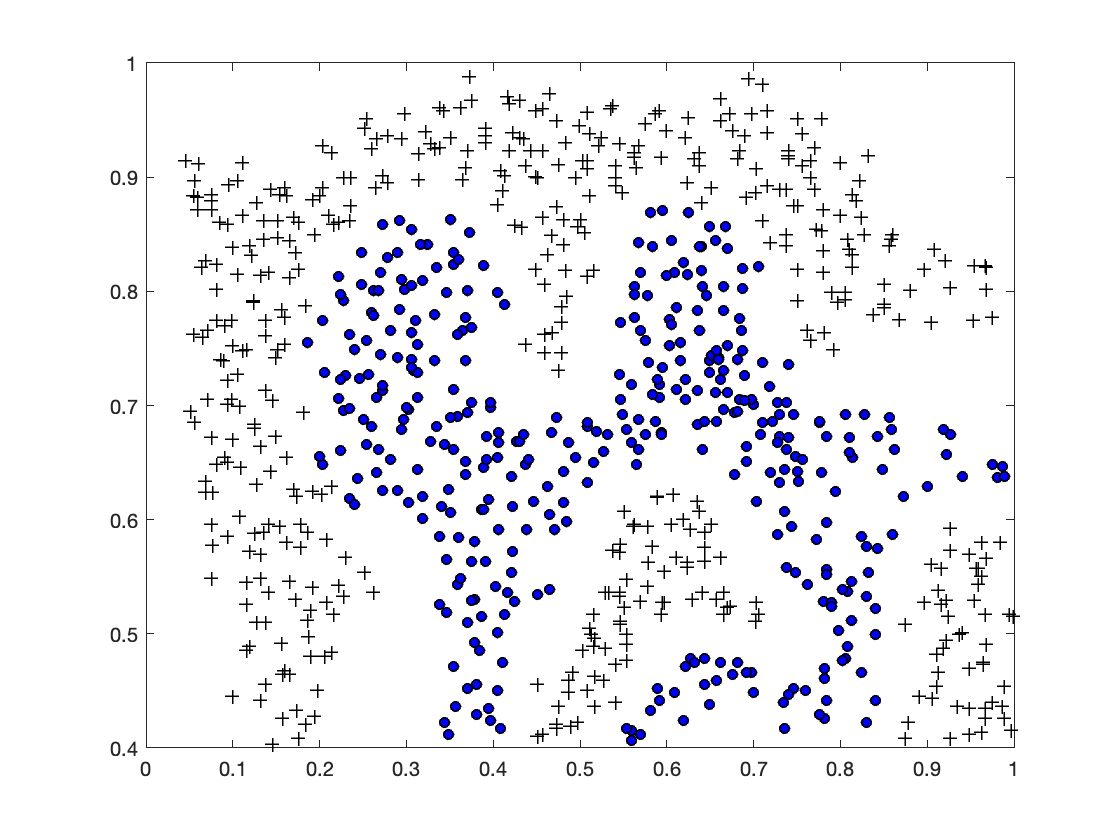

plot_raw(x_train, y_train, 1)

## Train data

alpha_mat = zeros(16, n);
beta_mat = zeros(16, p);
beta_0_mat = zeros(4, 4);

for i=1:length(gamma_list)
    for j=1:length(C_list)
        gamma = gamma_list(i);
        C = C_list(j);
        [alpha, beta, beta_0] = train_svm(x_train, y_train, gamma, C);
        alpha_mat(4*(i-1)+j,:) = alpha;
        beta_mat(4*(i-1)+j,:) = beta;
        beta_0_mat(i,j) = beta_0;
    end
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

## Draw boundary

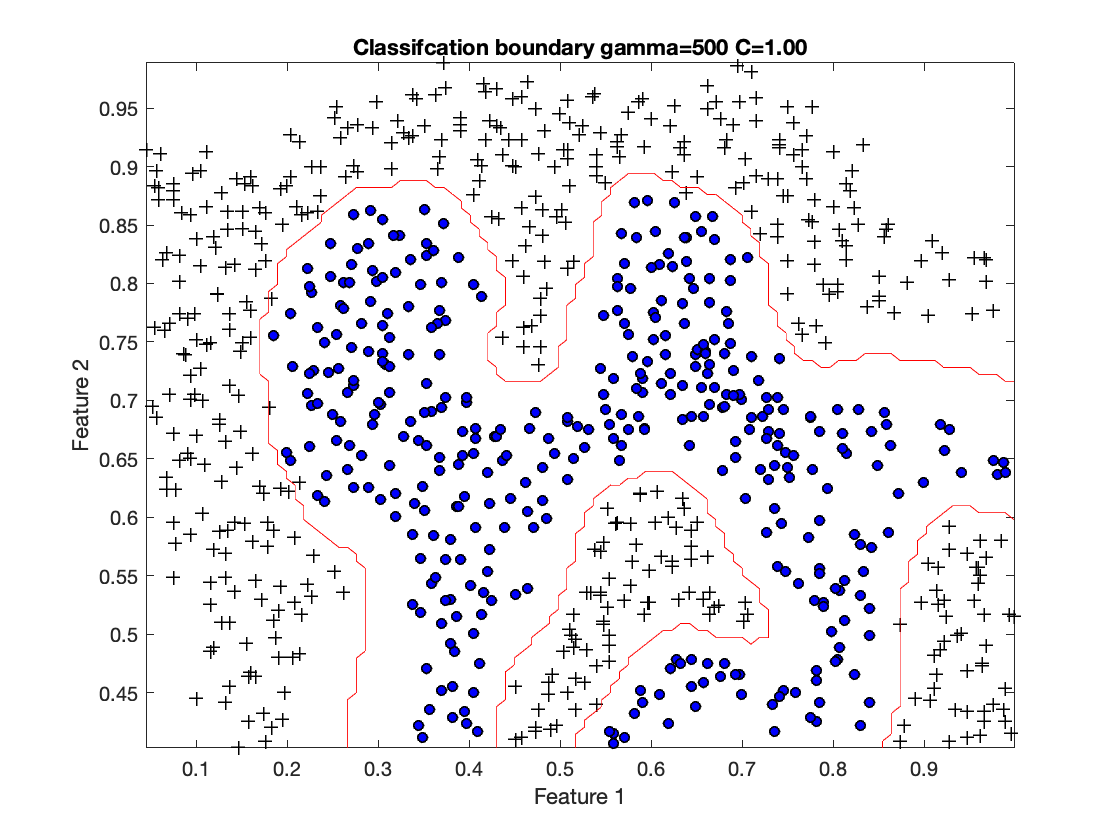

for i=1:length(gamma_list)
    for j=1:length(C_list)
        gamma = gamma_list(i);
        C = C_list(j);
        alpha = alpha_mat(4*(i-1)+j,:);
        beta = beta_mat(4*(i-1)+j,:);
        beta_0 = beta_0_mat(i,j);
        plot_boundary(x_train, y_train, gamma, C, alpha, beta, beta_0);
    end
end

## Identify support vectors

gamma=10, C=0.01, num of support vectors: 768

gamma=10, C=0.10, num of support vectors: 584

gamma=10, C=0.50, num of support vectors: 447

gamma=10, C=1.00, num of support vectors: 401

gamma=50, C=0.01, num of support vectors: 770

gamma=50, C=0.10, num of support vectors: 448

gamma=50, C=0.50, num of support vectors: 249

gamma=50, C=1.00, num of support vectors: 185

gamma=100, C=0.01, num of support vectors: 772

gamma=100, C=0.10, num of support vectors: 449

gamma=100, C=0.50, num of support vectors: 210

gamma=100, C=1.00, num of support vectors: 157

gamma=500, C=0.01, num of support vectors: 805

gamma=500, C=0.10, num of support vectors: 745

gamma=500, C=0.50, num of support vectors: 347

gamma=500, C=1.00, num of support vectors: 281

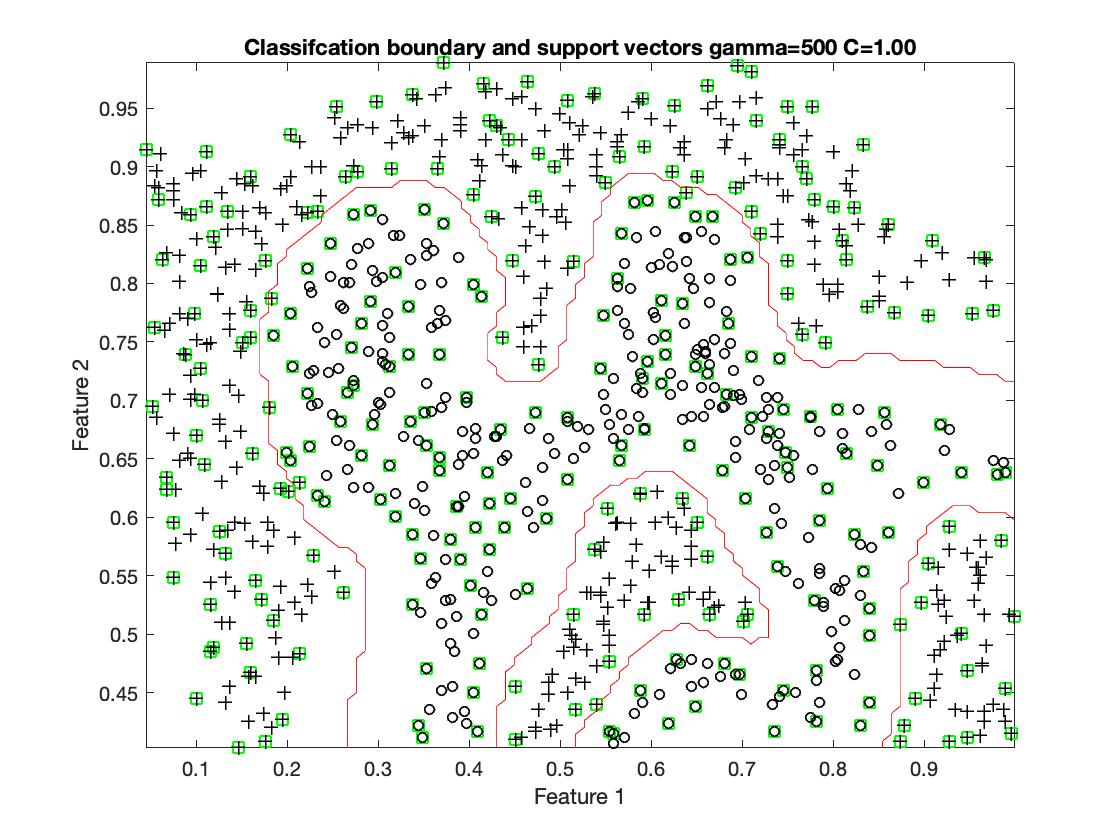

for i=1:length(gamma_list)
    for j=1:length(C_list)
        gamma = gamma_list(i);
        C = C_list(j);
        alpha = alpha_mat(4*(i-1)+j,:);
        beta = beta_mat(4*(i-1)+j,:);
        beta_0 = beta_0_mat(i,j);
        find_support_vectors(x_train, y_train, ...
                             gamma, C, alpha, beta, beta_0);
    end
end

## Classification error

for i=1:length(gamma_list)
    for j=1:length(C_list)
        gamma = gamma_list(i);
        C = C_list(j);
        alpha = alpha_mat(4*(i-1)+j,:);
        beta = beta_mat(4*(i-1)+j,:);
        beta_0 = beta_0_mat(i,j);
        [error, error_ps, error_ng]=classification_error(...
            x_train, y_train, gamma, C, alpha, beta, beta_0);
        fprintf(['gamma=%d, C=%.2f, classification error: %.4f;' ...
            ' False positive: %.4f; False negative: %.4f\n'], ...
            gamma, C, error, error_ps, error_ng);
    end
end

gamma=10, C=0.01, classification error: 0.3129; False positive: 0.0000; False negative: 0.5625
gamma=10, C=0.10, classification error: 0.4183; False positive: 0.0000; False negative: 0.7521
gamma=10, C=0.50, classification error: 0.4612; False positive: 0.0000; False negative: 0.8292
gamma=10, C=1.00, classification error: 0.4403; False positive: 0.0000; False negative: 0.7917
gamma=50, C=0.01, classification error: 0.0950; False positive: 0.0470; False negative: 0.1333
gamma=50, C=0.10, classification error: 0.0614; False positive: 0.0261; False negative: 0.0896
gamma=50, C=0.50, classification error: 0.0197; False positive: 0.0000; False negative: 0.0354
gamma=50, C=1.00, classification error: 0.0104; False positive: 0.0000; False negative: 0.0187
gamma=100, C=0.01, classification error: 0.0463; False positive: 0.0392; False negative: 0.0521
gamma=100, C=0.10, classification error: 0.0185; False positive: 0.0026; False negative: 0.0312
gamma=100, C=0.50, classification error: 0.0070;